load('zzd.mat','zzd')
load('t.mat','t')
load('y_exprm.mat','y_exprm')

% save('zzd.mat','zzd')
% % t = dt:dt:tf;
% save('t.mat','t')
% save('y_exprm.mat','y_exprm')

dist_ref  = [];
dist_expm = [];
% y_exprm__   = [y_exprm(1:end-1,:); y_exprm(end,:)];
% y_exprm__   = y_exprm(1:end-1,:);
% y_exprm__   = [zeros(1,3); y_exprm];
y_exprm__   = y_exprm;
zzd__       = [zeros(3,1), zzd];
t__         = [0, t];

alpha       = -pi * 0.068;
R_aft    = [cos(alpha),  sin(alpha), 0;...
            -sin(alpha), cos(alpha), 0;...
            0         , 0,         1];
for i = 1:size(y_exprm__,1)
    y_exprm__(i,:) = (R_aft*y_exprm(i,:)')';
end
% y_exprm__(2:end,1) = y_exprm__(:,1)-y_exprm__(2,1);

% for i = 1:size(zzd__,2)
%     dist_ref  = [dist_ref,  norm(zzd__(:,i))];
%     dist_expm = [dist_expm, norm(y_exprm__(i,1:3))];
% end
% dist_error = abs(dist_ref - dist_expm);
dist_error = [];
for i = 1:size(zzd__,2)
    % dist_ref  = [dist_ref,  norm(zzd__(:,i))];
    % dist_expm = [dist_expm, norm(y_exprm__(i,1:3))];
    dist_error = [dist_error, norm(zzd__(:,i)' - y_exprm__(i,1:3))];
end
% dist_error = abs(dist_ref - dist_expm);
max(dist_error(10:end))

ans = single
2.6488

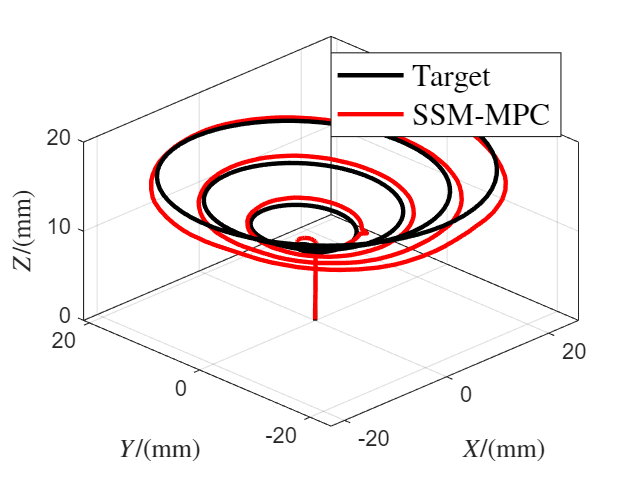

figure; hold on
% plot3(zzd__(1,1:100),zzd__(2,1:100),zzd__(3,1:100),'k-',LineWidth=2,DisplayName='Target')
% plot3(y_exprm__(1:100,1),y_exprm__(1:100,2),y_exprm__(1:100,3),'r-',LineWidth=2,DisplayName='SSM-MPC')
plot3(zzd__(1,:),zzd__(2,:),zzd__(3,:),'k-',LineWidth=2,DisplayName='Target')
plot3(y_exprm__(:,1),y_exprm__(:,2),y_exprm__(:,3),'r-',LineWidth=2,DisplayName='SSM-MPC')
% grid on
xlabel('$X$/(mm)',Interpreter='latex',FontSize=12)
ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
zlabel('$Z$/(mm)',Interpreter='latex',FontSize=12)

legend('show',Interpreter='latex',fontsize=14)
box on
grid on
view(-45,40)

% axis equal

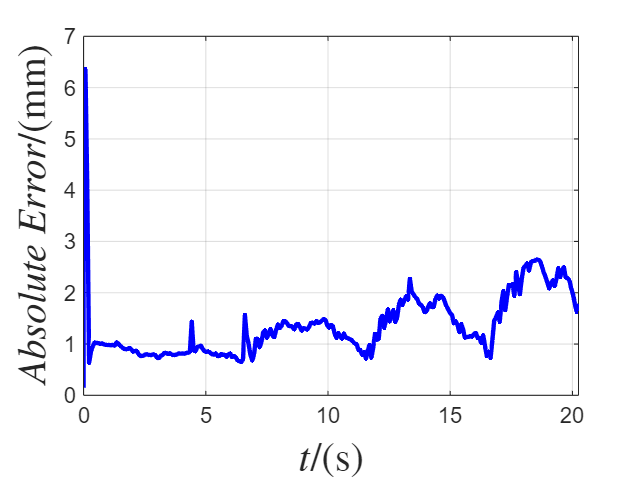

figure;
% subplot(3,1,1)
plot(t__,dist_error,'b-',LineWidth=2)
xlim([t__(1),t__(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=18)
ylabel('$Absolute$ $Error$/(mm)',Interpreter='latex',FontSize=18)


% subplot(3,1,2)
% plot(t__,dist_error/430.*100,'b-',LineWidth=2)
% xlim([t__(1),t__(end)])
% grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
% ylabel('$Relative$ $Error$/(\%)',Interpreter='latex',FontSize=10)

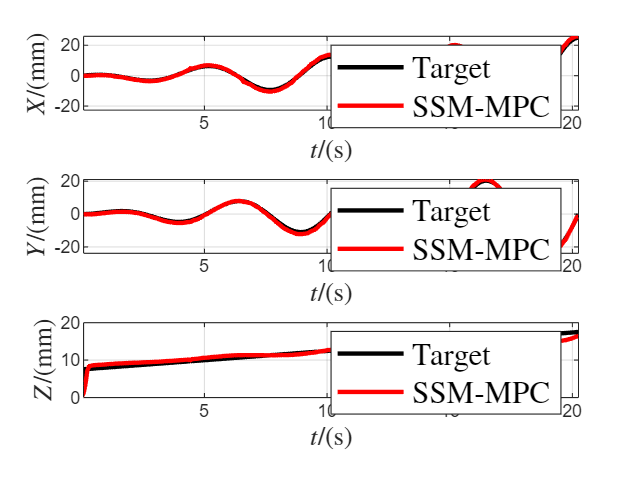

figure; 
subplot(3,1,1); hold on
plot(t__,zzd__(1,:),'k-',LineWidth=2,DisplayName='Target')
plot(t__,y_exprm__(:,1),'r-',LineWidth=2,DisplayName='SSM-MPC')
xlim([t(1)-0.001,t(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$X$/(mm)',Interpreter='latex',FontSize=12)
legend('show',Interpreter='latex',fontsize=14)
box on

subplot(3,1,2); hold on
plot(t__,zzd__(2,:),'k-',LineWidth=2,DisplayName='Target')
plot(t__,y_exprm__(:,2),'r-',LineWidth=2,DisplayName='SSM-MPC')
xlim([t(1)-0.001,t(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
legend('show',Interpreter='latex',fontsize=14)
box on

subplot(3,1,3); hold on
plot(t__,zzd__(3,:),'k-',LineWidth=2,DisplayName='Target')
plot(t__,y_exprm__(:,3),'r-',LineWidth=2,DisplayName='SSM-MPC')
xlim([t(1)-0.001,t(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$Z$/(mm)',Interpreter='latex',FontSize=12)
legend('show',Interpreter='latex',fontsize=14)
box on

% figure; hold on
% plot(t__,zzd__(2,:),'k-',LineWidth=2,DisplayName='Target')
% plot(t__,y_exprm__(:,2),'r-',LineWidth=2,DisplayName='SSM-MPC')
% % xlim([t(1),t(end)])
% grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
% ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
% legend('show',Interpreter='latex',fontsize=14)
% box on

% figure; hold on
% % plot(t__,zzd__(3,:),'r-',LineWidth=2,DisplayName='Desired')
% plot(t__,y_exprm__(:,3),'r-',LineWidth=2,DisplayName='SSM-MPC')
% % xlim([t(1),t(end)])
% grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
% ylabel('$Z$/(mm)',Interpreter='latex',FontSize=12)
% legend('show',Interpreter='latex',fontsize=14)
% box on